# Demo: Simulating Fading Channels

MATLAB has many excellent routines for simulating various multi-path fading models. In going through this demo you will learn to:

- Simulate fractional delays using the DSP toolbox

- Describe multi-path channels with arrays of delays and angles

- Plot the time-varying frequency response for a deterministic multi-path channel

- Load the deterministic 3GPP NR channel model

- Simulate narrowband statistical fading models 

## Simulating a Fractional Delay

Simulating wireless channels requires simulating fractional delays. This can be done easily in MATLAB as follows.

tau = [0,8,8.2,8.5];  % Delays in fractions of a sample

% Create a fractional delay object from the DSP toolbox
% We select the Farrow interpolation, which is a fast
% and accurate method.  It is important to select the options
% correctly
dly = dsp.VariableFractionalDelay(...
    'InterpolationMethod', 'Farrow','FilterLength',8,...
    'FarrowSmallDelayAction','Use off-centered kernel');

% Generate a sequence of length nt with an impulse at t0
nt = 32;
t0 = 5;
x = zeros(nt,1);
x(t0+1) = 1;
tx = (0:nt-1)';

% Create delays of the sequence
y = dly.step(x,tau);    

% Plot the results along with the theoretical sinc filter
ntau = length(tau);
for i = 1:ntau
    subplot(ntau,1,i);
    stem(tx,y(:,i));
    hold on;
    t = linspace(0,nt,1000)';
    plot(t, sinc(t-tau(i)-t0), '--');
    hold off;
end

## Two path channel: Variations in Time

To illustrate the concepts of multipath fading, we consider a simple two path channel.

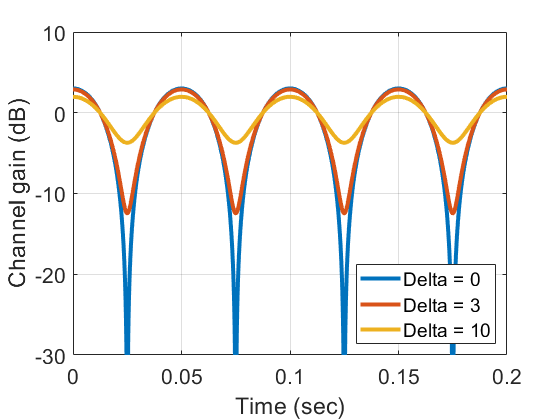

% Parameters
dly = [0,0.2]'*1e-6;  % path delays in us
fdmax = 10;         % max doppler shift
theta = [0,pi]';    % angles of the paths
deltaTest = [0,3,10];  % difference in dB between paths

% We first compute the narrowband response over time
% for a fixed frequency
fd = fdmax*cos(theta); % doppler shifts of the paths
ndel = length(deltaTest);

% Times to plot
nt = 1000;
t = linspace(0,0.2,nt)';

% Compute the channel response over time for each delta value
H = zeros(nt,ndel);
legStr = cell(ndel,1);
for i = (1:ndel)
    
    % Compute path gains
    del = deltaTest(i);
    hpow = [1 10.^(-0.1*del)];
    hpow = hpow / sum(hpow);
    h = sqrt(hpow)';
    
    % Compute the channel response
    H(:,i) = exp(2*pi*1i*t*fd')*h;
    
    % Add to legend
    stri = sprintf('Delta = %d', del);
    legStr{i} = stri;
end

subplot(1,1,1);
P = 10*log10(abs(H).^2);
plot(t,P,'-','LineWidth',3),
grid on,
ylim([-30 10]);
set(gca,'Fontsize', 16);

xlabel('Time (sec)');
ylabel('Channel gain (dB)');
legend(legStr, 'Location', 'SouthEast');

## Two-path channel: Variations in frequency

We can now fix the time and plot the variations in frequency

% Frequencies to plot
nf = 1000;
f = linspace(-10,10,nf)'*1e6;

% Compute the channel response over time for each delta value
H = zeros(nf,ndel);
legStr = cell(ndel,1);
for i = (1:ndel)
    
    % Compute path gains
    del = deltaTest(i);
    hpow = [1 10.^(-0.1*del)];
    hpow = hpow / sum(hpow);
    h = sqrt(hpow)';
    
    % Compute the channel response
    H(:,i) = exp(2*pi*1i*f*dly')*h;
    
    % Add to legend
    stri = sprintf('Delta = %d', del);
    legStr{i} = stri;
end

subplot(1,1,1);
P = 10*log10(abs(H).^2);
plot(f/1e6,P,'-','LineWidth',3),
grid on,
ylim([-30 10]);
set(gca,'Fontsize', 16);
xlabel('Freq (MHz)');
ylabel('Channel gain (dB)');
legend(legStr, 'Location', 'SouthEast');


## Simulating a Deterministic 3GPP Channel Model

We next simulate a narrowband on a deterministic channel.   The 3GPP NR standard has several deterministic channel models which are used for test cases in evaluating system.  For this example, we will use the model called 'CDL-C'. Since this model is widely-used, it is incorporated in MATLAB's excellent 5G Toolbox.  We get the data structure with the path info as follows.

fc = 2.3e9;           % carrier in Hz
dlySpread = 0.5e-6;   % delay spread in seconds

% Get NR channel object and data
chan = nrCDLChannel('DelayProfile','CDL-C',...
    'DelaySpread',dlySpread, 'CarrierFrequency', fc, ...
    'NormalizePathGains', true);
chaninfo = info(chan);


The `chaninfo` structure has the various parameters of each path including its gain, delay  and angle of arrival and departure.  

gain = chaninfo.AveragePathGains';
aoaAz  = chaninfo.AnglesAoA';
aoaEl = 90-chaninfo.AnglesZoA';
dly = chaninfo.PathDelays';

We can plot the power-delay profile using a stem plot.

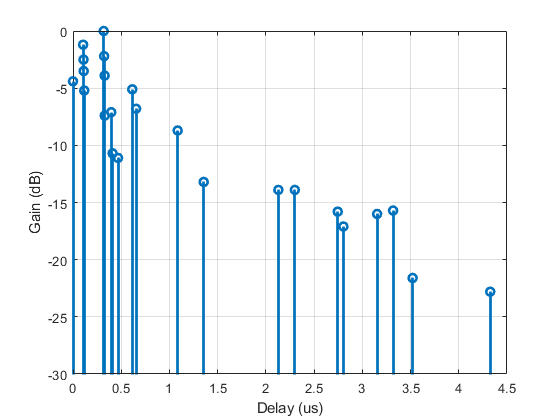

clf;
stem(dly*1e6, gain, 'BaseValue', -30, 'LineWidth', 2);
grid on;
xlabel('Delay (us)');

ylabel('Gain (dB)')

We can also plot the paths by their angle of arrival using the `polarplot` function.  In this plot the length of the line corresponds to its strength.  We see this is a* rich scattering environment *since there are paths arriving from all angles.

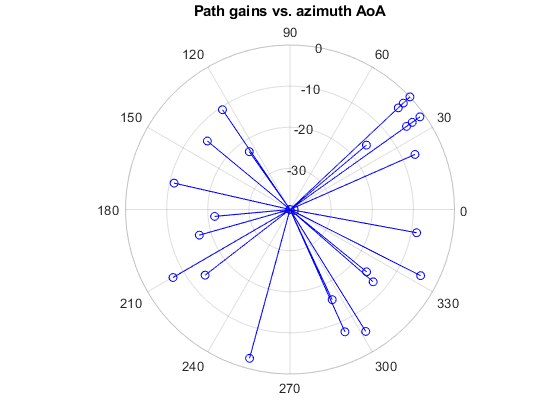

npath = length(gain);
g0 = 40;

for i = 1:npath
    gi = max(-g0, gain(i));
    polarplot([aoaAz(i), aoaAz(i)], [-g0, gi], 'b-o');
    hold on;
end
rlim([-g0, 0]);
hold off;
title('Path gains vs. azimuth AoA');

We next compute the Doppler shift for each path.  Suppose the UE has a velocity vector `ueVel`.  Then the Doppler of path `i` can be computed by:

where `vc` is the speed of light, `arr(i,:)` is a unit vector in the direction of the path.  

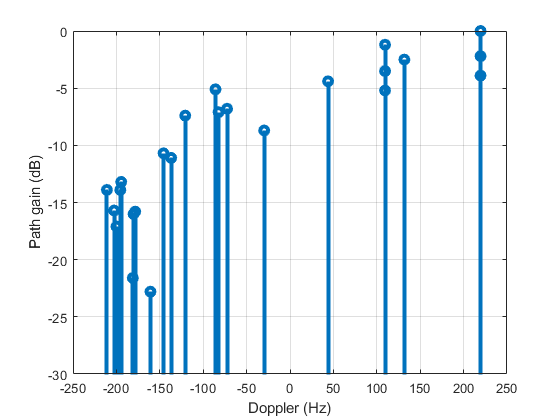


% UE velocity vector in m/s
ueVel = [30; 0; 0];

% Create a unit vectors in the direction of the path
[ux, uy, uz] = sph2cart(deg2rad(aoaAz), deg2rad(aoaEl), 1);
U = [ux uy uz];

% Compute Doppler shift
vc = physconst('Lightspeed');
fd = -fc/vc*U*ueVel;

% Plot the Doppler shifts
clf;
stem(fd, gain, 'BaseValue', -30, 'LineWidth', 3);
grid on;
xlabel('Doppler (Hz)');
ylabel('Path gain (dB)');


We now generate the narrowband fading by 

where `A`(k) is the path gain, `fd(k)` is its Doppler and `phase(k)` is a random initial phase.

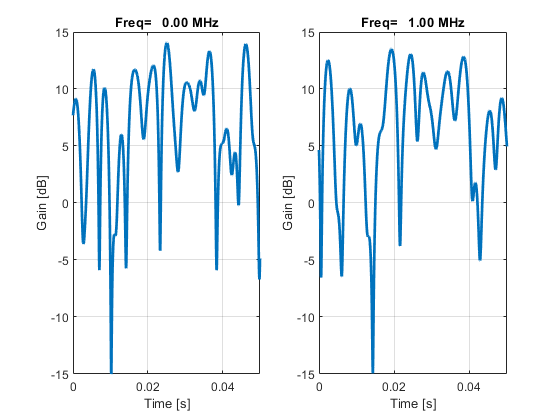

% Compute the fading gain over time
t = linspace(0,0.05,1000)';
npath = length(gain);

% Random initial phase on each path at freq = 0
phi0 = 2*pi*rand(npath,1);

% Number of frequencies to test
ftest = [0,1e6];
nfreq = length(ftest);

for i=1:nfreq
    % Initial phase
    phi = phi0 - 2*pi*ftest(i)*dly;
    
    % Gains on each path
    G = db2mag(gain).*exp(1i*(2*pi*fd*t' + phi) );
    
    % Sum over paths
    g = sum(G,1).';
    
    % Get power gain
    gpow = 20*log10(abs(g));
    
    subplot(1,nfreq,i);
    plot(t, gpow, 'Linewidth', 2);
    grid on;
    xlabel('Time [s]');
    ylabel('Gain [dB]');
    title(sprintf('Freq=%7.2f MHz', ftest(i)/1e6));
    ylim([-15,15]);
    xlim([0,0.05]);
    
end



## Simulating Stochastic Fading

MATLAB has excellent tools to simulate standard stochastic fading channels. The code below plots random samples of fading paths under various fading models. Plotted is the gain magnitude and phase over time. We can observe the following:

- Jake's spectrum has the fastest variations since it contains paths with Doppler from [-fdmax, fdmax]

- The asymmetric Jake's spectrum has paths from [a*fdmax, b*fdmax] where [a,b] are specified in the construction of the Doppler model. In models 2 and 3, [a,b] is a small interval and the Doppler spread is small. As a result, the channel gain changes slowly

- In model 2 and 3, there is a linear phase across time depending on the center Doppler shift. In model 2, the center is close to 0, so the angle does not change. But, in model 3, the angle changes linearly over time

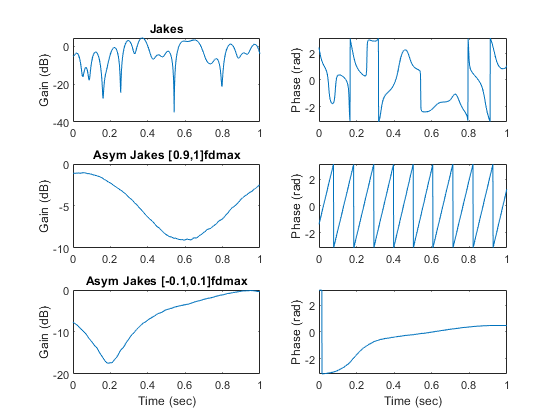

% Parameters
fsym = 1e3;     % sample rate in Hz
fdmax = 10;     % max Doppler rate in Hz
nt = 1e3;       % number of samples to simulate

% Create an input sequence
t = (0:nt-1)'/fsym;
x = ones(nt,1);

% Create Doppler models
nmod = 3;
dopMod = cell(nmod,1);
dopMod{1} = doppler('Jakes');
dopMod{2} = doppler('Asymmetric Jakes', [0.9 1]);
dopMod{3} = doppler('Asymmetric Jakes', [-0.1 0.1]);
titleStr = {'Jakes', ...
    'Asym Jakes [0.9,1]fdmax', ...
    'Asym Jakes [-0.1,0.1]fdmax'};

% Simulate the channel gains for each model
for i = (1:nmod)
    % Create a Rayleigh fading object
    chan = comm.RayleighChannel(...
        'SampleRate', fsym, 'AveragePathGains', 0, ...
        'MaximumDopplerShift', fdmax,...
        'DopplerSpectrum', dopMod{i}, ...
        'PathGainsOutputPort', true);
    
    % Run the channel
    [y, gain] = chan.step(x);
    
    % Plot the results
    subplot(nmod,2,2*i-1);
    plot(t, 20*log10(abs(gain)));
    title(titleStr{i});
    if i == nmod
        xlabel('Time (sec)');
    end
    ylabel('Gain (dB)');
    
    subplot(nmod,2,2*i);
    plot(t, angle(gain));
    if i == nmod
        xlabel('Time (sec)');
    end
    ylabel('Phase (rad)');
    
end

## Plotting the Auto-Correlation 

We next compute the auto-correlation for a narrowband model.  The autocorrelation of a multi-path process with random angle `theta` is:

where `fdmax` is the max Doppler shift, `t` is the time and the expectation is over the angle `theta`.  We plot this function for:

- `theta` uniform on [-180, 180] degrees

- `theta` uniform on [-60, 60] degrees

We can use MATLAB's numerical integral routine `integral`.   

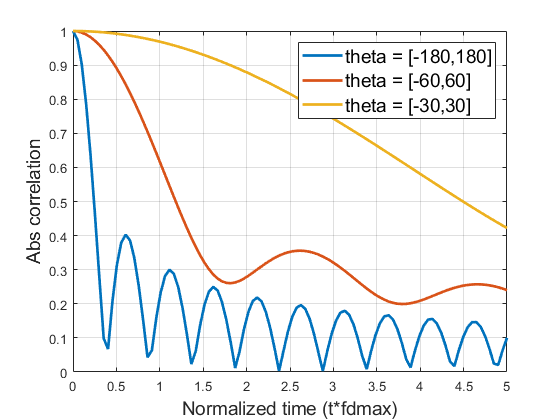

% Function handle for the integrand
rfun = @(theta,tf) exp(1i*2*pi*cos(deg2rad(theta))*tf);

% Angle ranges to test
thetaMaxTest = [180, 60, 30];
ntheta = length(thetaMaxTest);

% Times to test:  
t = linspace(0,5,100);
nt = length(t);

% Compute correlation for each angle range and time
Rcorr = zeros(nt, ntheta);
legStr = cell(ntheta,1);
for j = 1:ntheta
    thetam = thetaMaxTest(j);
    legStr{j} = sprintf('theta = [-%d,%d]', thetam, thetam);
    for i = 1:nt    
    
        Z1 = integral(@(theta) rfun(theta,t(i)), -thetam, thetam);
        Rcorr(i,j) = abs(Z1/(2*thetam));
    end
end

plot(t, Rcorr, 'LineWidth', 2);
grid on;
xlabel('Normalized time (t*fdmax)', 'FontSize', 14);
ylabel('Abs correlation', 'FontSize', 14);
legend(legStr, 'FontSize', 14);
